ep3 - síntese direta

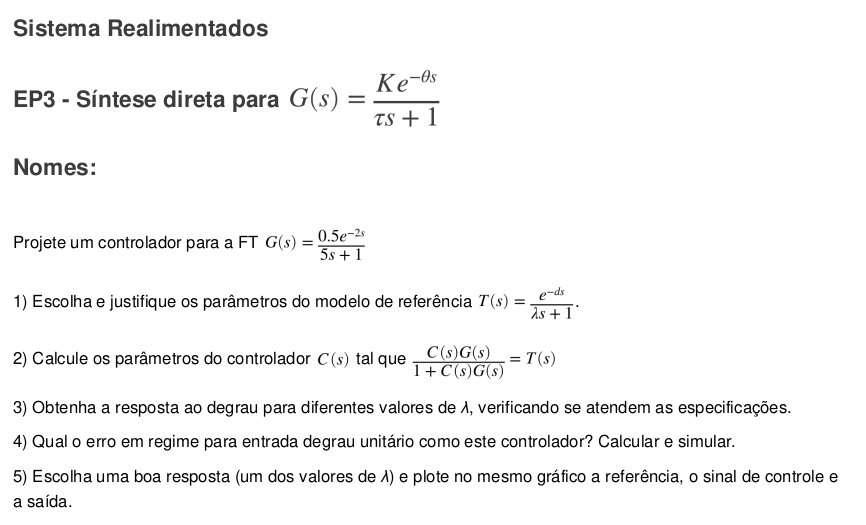

s = tf('s');

1)

2 e 3)

G = 0.5*exp(-2*s)/(5*s+1)

G =
 
                0.5
  exp(-2*s) * -------
              5 s + 1
 
Continuous-time transfer function.
Model Properties


g_pade = pade(G)

g_pade =
 
   -0.5 s + 0.5
  ---------------
  5 s^2 + 6 s + 1
 
Continuous-time transfer function.
Model Properties


lambda = 1

lambda = 1

d = 2

d = 2

tau = 5

tau = 5

k = 0.5

k = 0.5000

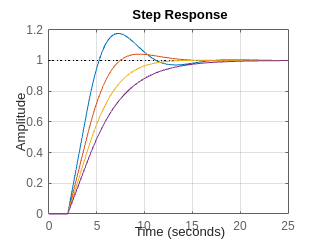

figure;
for lambda = 1:4
    
    k_mf = tau/((d+lambda)*k);
    GC = k_mf*(1 + (1/(5*s)));
    M = feedback(GC*G,1);
    step(M);
    hold on;
end
grid on;
hold off

4)

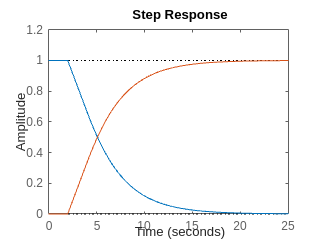

M_erro = feedback(1,GC*G);
step(M_erro,1-M_erro)

5)

sinal de controle é C/1+CG